load("C:\Users\maxxm\OneDrive\Loughborough Year 2\Semester 2\mnist.mat");
XTraining = reshapeInput(XTrain);
XTesting = reshapeInput(XTest);

YTraining = full(ind2vec(YTrain'+1));
YTesting = full(ind2vec(YTest'+1));

inputSize = size(XTraining, 2);
hiddenSizes = 0:50:2000; 
numHiddenSizes = length(hiddenSizes);
accuracyResults = zeros(numHiddenSizes, 1);
totalCorrectLabels = 0;
relu = @(x) max(x, 0);

tic
for i = 1:1:numHiddenSizes
    hiddenSize = hiddenSizes(i);
    inputWeighting = normrnd(0, 1, [inputSize, hiddenSize]);
    biases = normrnd(0, 1, [1, hiddenSize]);

    hiddenNodes = relu(XTraining * inputWeighting + biases);

    outputWeight = pinv(hiddenNodes) * YTraining';

    predictFunction = @(X) relu(X * inputWeighting + biases) * outputWeight;

    Prediction = predictFunction(XTesting);
    [~, predictedLabels] = max(Prediction, [], 2);
    [~, actualLabels] = max(YTesting, [], 2);
    predictedLabels = predictedLabels(:);
    actualLabels = actualLabels(:);
    predictedLabels = predictedLabels';
    for j = 1:1:length(actualLabels)
        if predictedLabels(j) == actualLabels(j)
            totalCorrectLabels = totalCorrectLabels + 1;
        end
    end
    accuracy = totalCorrectLabels / length(actualLabels);
    accuracyResults(i) = accuracy;
end
toc

Elapsed time is 249.734080 seconds.


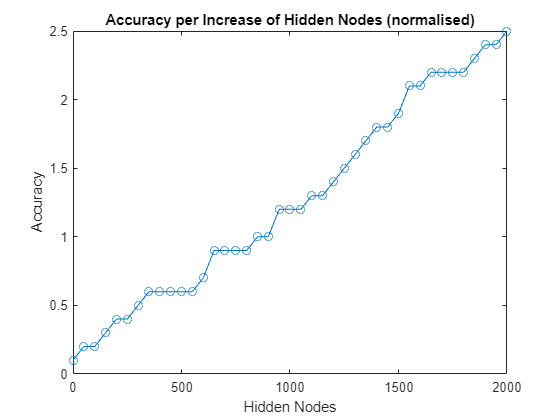

plot(hiddenSizes, accuracyResults, '-o');
xlabel('Hidden Nodes');
ylabel('Accuracy');
title('Accuracy per Increase of Hidden Nodes (normalised)');


fprintf('Accuracy for %d hidden nodes: %f\n', hiddenSize, accuracy);

Accuracy for 2000 hidden nodes: 2.500000



fprintf('Accuracy for %d hidden nodes: %f\n', hiddenSize, accuracy);

Accuracy for 2000 hidden nodes: 2.500000


function A = reshapeInput(InputArray)
    rowLengthA = length(InputArray(1,1,1,:));
    columnLengthA = (length(InputArray(:,1,1,1)))^2;
    A = reshape(InputArray, rowLengthA, columnLengthA);
end